# circular_buffer_filter.m

## Load wave file

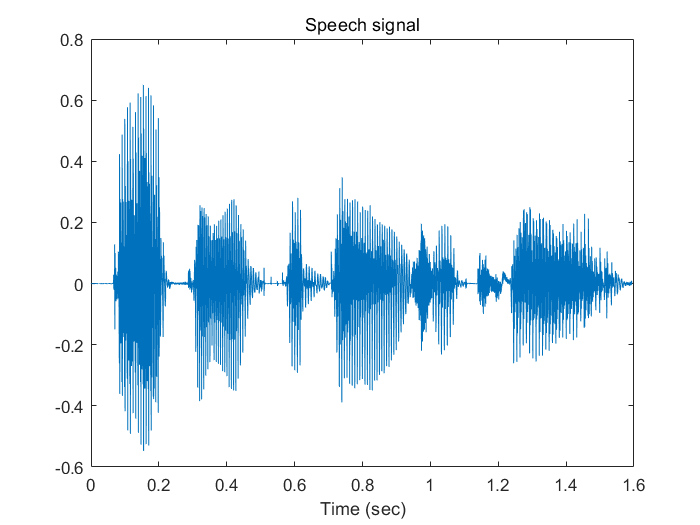

% [x, Fs] = audioread('author.wav');
[x, Fs] = audioread('author.wav');

N = length(x);
n = 1:N;
t = n/Fs;

figure(1)
clf
plot(t, x)
xlabel('Time (sec)')
title('Speech signal')

## Simulate a clipped signal

Just to hear what it sounds like

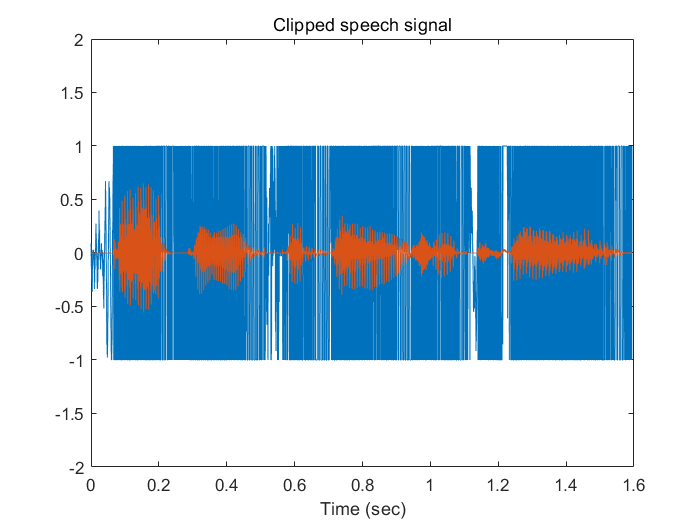

x_clipped =  min(1, max(-1, x*1000));

figure(1)
clf
plot(t, x_clipped, t, x)
xlabel('Time (sec)')
title('Clipped speech signal')
ylim([-2 2])

## Make filter

band-pass filter

a = [1.0, zeros(1,799), 0.8]

a =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


b = 1

b =      1


## Pole-zero diagram

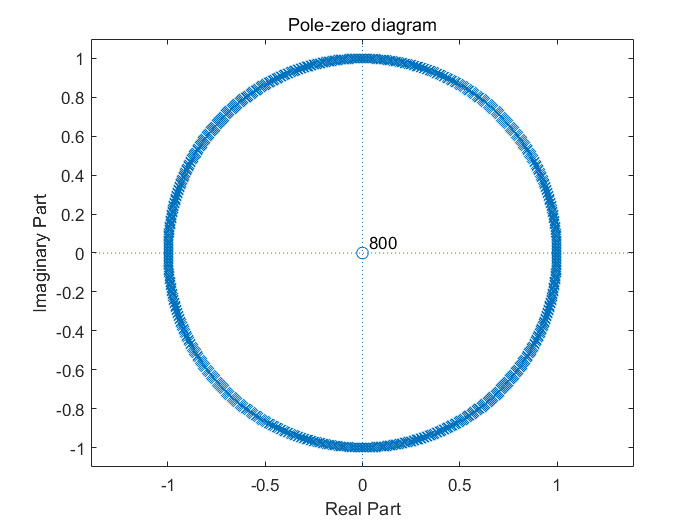

figure(1)
clf
zplane(b, a)
title('Pole-zero diagram')

## Frequency response

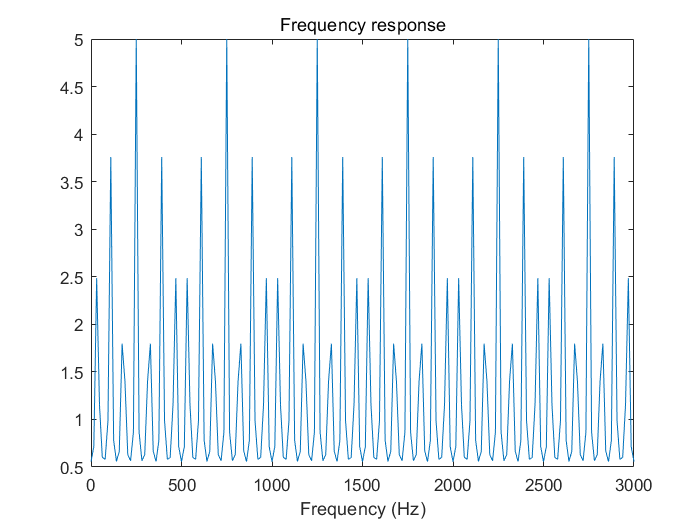

[H, om] = freqz(b, a);
f = om*Fs/(2*pi);
figure(1)
clf
plot(f, abs(H))
xlabel('Frequency (Hz)')
xlim([0 3000])
title('Frequency response')

## Impulse response

discrete-time plot

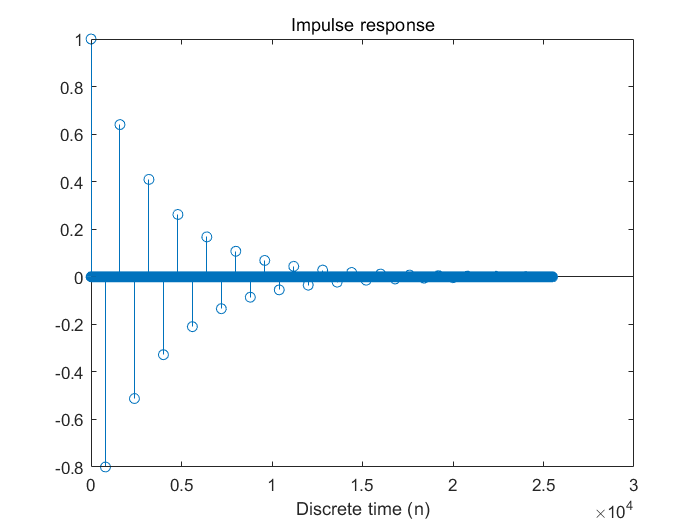

imp = [1 zeros(1, N)];
h = filter(b, a, imp);

figure(1)
clf
stem(0:N, h)
xlabel('Discrete time (n)')
title('Impulse response')

## Impulse response

continuous-time plot

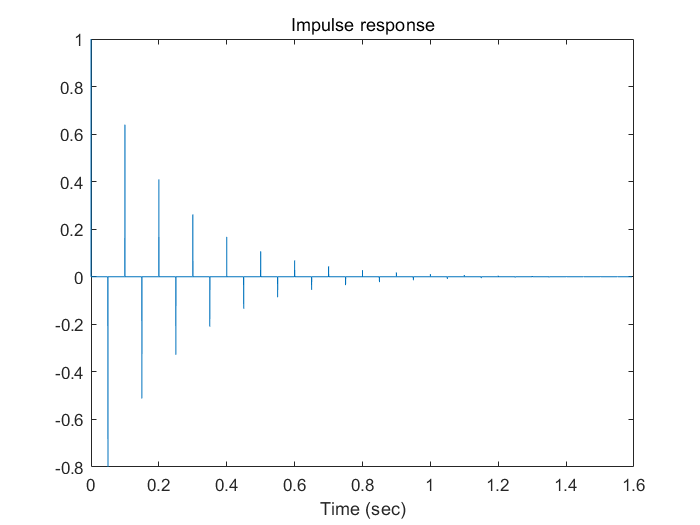

figure(1)
clf
plot((0:N)/Fs, h)
xlabel('Time (sec)')
title('Impulse response')

## Apply filter to speech signal

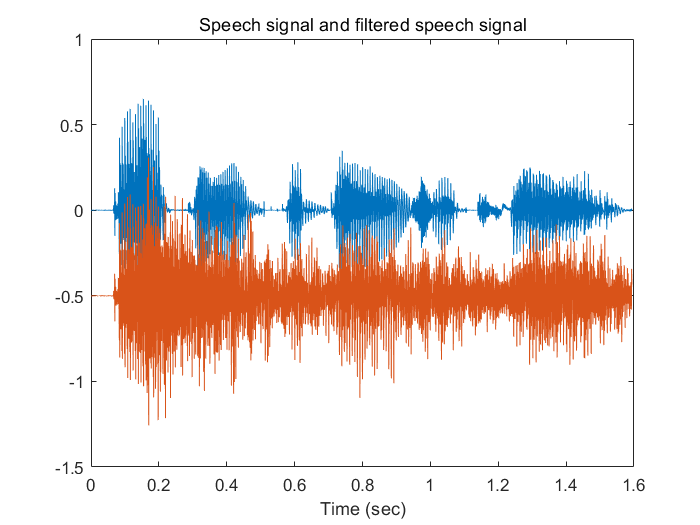

y = filter(b, a, x);   % implement difference equation

figure(1)
clf
plot(t, x, t, y - 0.5)
xlabel('Time (sec)')
title('Speech signal and filtered speech signal')
zoom xon

## Write output signal to wave file

% audiowrite('output_matlab.wav', y, Fs);
audiowrite('output_matlab_f.wav',y, Fs);

sound(x, Fs)

sound(y, Fs)

## Filter coefficients

Copy these coefficients into Python program to implement the same filter. Display in long format for higher accuracy.

format long
b'

ans =      1


a'

ans =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0
